# **Asset Price Modelling using Monte-Carlo Simulations**

#### **Puneet Mishra, Ruchir Sharma**

#### **pmishra_be17@thapar.edu, rsharma_be17@thapar.edu**

An asset-price model using historical prices. Volatility of the asset is modeled as the random variable that changes over time and each iteration. For modelling the future price behavior, Monte Carlo simulations were performed. The method tries to cover all future outcomes based on volatility and with sufficient number of simulations and rows of clean data, a  gaussian cumulative distribution curve can be derived for the most likely price range estimate. Note, the following model is based on a lot of assumptions, especially the assumption that the modelled market is efficient.

**1. Introduction**

We have assumed two components which influence an asset's price movements, namely, drift and volatility. The first component, Drift, which can be derived from historical data of an asset, is a constant directional movement. The second component, market volatility, is a random variable, which is a result of random price changes due to market sentiment. By analyzing an asset's historical price data, we can calculate the drift, mean, standard deviation, and variance of the price movement of the same. These form the basis for our Monte Carlo simulation. The functions defined for this script are at the bottom.

**2. Loading Data**

We shall now load the data of the assets in considerations. I shall be considering the historical data for the following listings:

- Microsoft (MSFT) : '1990 to 7th Feb 2020

- Apple (AAPL) : '1990 to 7th Feb 2020

- SBI Cards (SBICARD) : March 2020 to 20th July 2020

- Microsoft (MSFT) : 8th Feb 2020 to 4th April

T_msft=readtable('MSFT_daily.csv','PreserveVariableNames',1);
T_aapl=readtable('AAPL_daily.csv','PreserveVariableNames',1);
T_sbicard=readtable('SBICARD_daily.csv','PreserveVariableNames',1);
T_test=readtable('MSFT_test.csv','PreserveVariableNames',1);

**4. Extracting the Closing Prices**

Using the all_to_close function to extract the closing price of all the days from the loaded data files.

msft_close=all_to_close(T_msft,4);
aapl_close=all_to_close(T_aapl,4);
sbicard_close=all_to_close(T_sbicard,4);
test_close=all_to_close(T_test,4);

**5.  Calculating Statistical Parameters And Daily Returns**

Calculating and storing the daily returns as well as the statistical parameters of the daily closing prices, namely,

1. Mean

2. Standard Devaiation

3. Variance

4. Drift

[msft_daily,msft_params]=calc_parameters(msft_close(30:5033));
[aapl_daily,aapl_params]=calc_parameters(aapl_close(30:5033));
[sbicard_daily,sbicard_params]=calc_parameters(sbicard_close(30:90));

**6. Running Monte-Carlo Simulations**

Here, I have defined the number of simulations to run and number of days to predict in the future. Following which, defined number of monte-carlo simulations are performed to calculate the closing prices in the future. I make use of the mcs_next_price function defined earlier. Also, we have held back 30 days for testing purposes.

days=30;
number_of_sims=1000;
msft_next_day_price=mcs_next_price(msft_close(30:5033),msft_params,days,number_of_sims);
aapl_next_day_price=mcs_next_price(aapl_close(30:5033),aapl_params,days,number_of_sims);
sbicard_next_day_price=mcs_next_price(sbicard_close(30:90),sbicard_params,30,number_of_sims);

**7.** **Plotting the Outcome of Simulations**

Now we shall see how my simulations performed. Let's see how the MSFT, AAPL and SBICARD assets performed with respect to actual data points of the future. Black line is the test data and reflects the actual price changes.

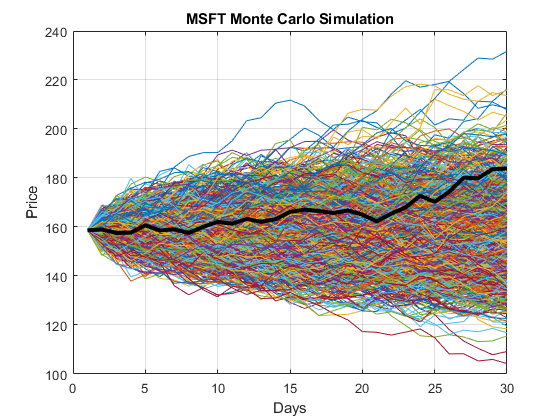

figure('Color','white','Name','Monte-Carlo Simulation','NumberTitle','off');
plot(msft_next_day_price)
grid on
title('MSFT Monte Carlo Simulation')
xlabel('Days')
ylabel('Price')
hold on
plot(msft_close(30:-1:1), 'LineWidth',3,'Color','black')

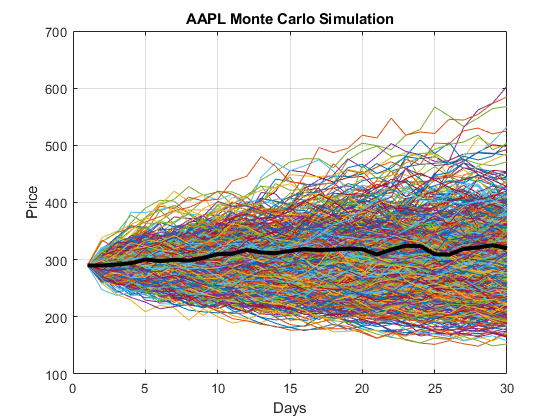

figure('Color','white');
plot(aapl_next_day_price)
grid on
title('AAPL Monte Carlo Simulation')
xlabel('Days')
ylabel('Price')
hold on
plot(aapl_close(30:-1:1), 'LineWidth',3,'Color','black')

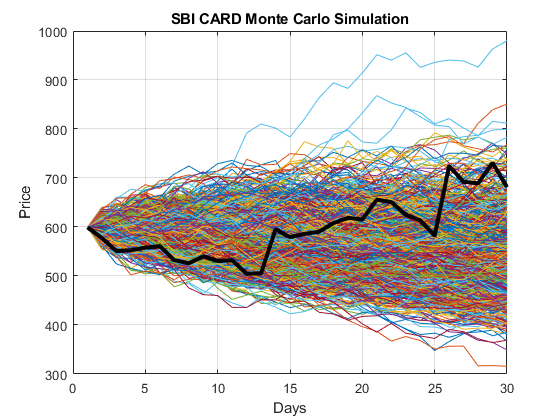

figure('Color','white');
plot(sbicard_next_day_price)
grid on
title('SBI CARD Monte Carlo Simulation')
xlabel('Days')
ylabel('Price')
hold on
plot(sbicard_close(30:-1:1), 'LineWidth',3,'Color','black')

As we can see, MSFT and AAPL simulations are able to describe the volatility accurately as the actual data is in the middle of the upper and lower range of the simulation. However, we see that SBICARD does not perform the same. But this can be attributed to the fact that SBICARD recently had its IPO and is highly moderated and volatile due to the COVID-19 panic at the markets.

**8. Plotting the Frequency Distributions**

Plotting the frequency distributions of the simulations and thus confirming if the resultant simulations are normally distributed and finding the range of the most likely price estimates. Yellow represents the simulated data and blue the actual data.

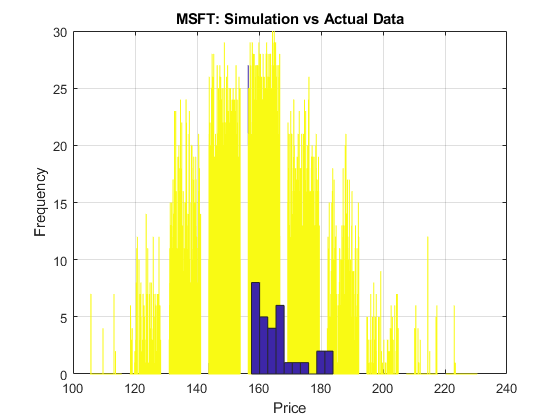

figure('Color','white')
hist(msft_next_day_price)
grid on
title('MSFT: Simulation vs Actual Data')
xlabel('Price')
ylabel('Frequency')
hold on
hist(msft_close(30:-1:1))

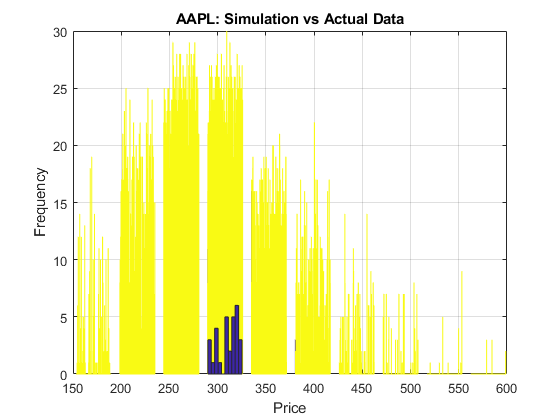

figure('Color','white')
hist(aapl_next_day_price)
grid on
title('AAPL: Simulation vs Actual Data')
xlabel('Price')
ylabel('Frequency')
hold on
hist(aapl_close(30:-1:1))

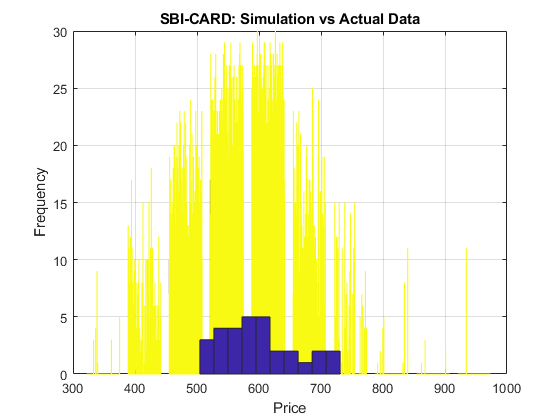

figure('Color','white')
hist(sbicard_next_day_price)
grid on
title('SBI-CARD: Simulation vs Actual Data')
xlabel('Price')
ylabel('Frequency')
hold on
hist(sbicard_close(30:-1:1))

As we can notice, our simulation and volatile model has managed to capture the actual future price volatility within 95% confidence interval.

**9. Conclusion**

The above experiments showcase the power and usefullness of monte-carlo simulations in cases where random variables are involved. Furthermore, this basic concept can be improved by incorporating more defined variables. 

**10. Appendix**

**10.1.** **Functions**

**         10.1.1.    all_to_close (Table, close_index)**

**Definition: **A function to extract the closing price column from the given historical data table of the asset in consideration.

**Input:**

-    ** Table** = Table of size (h,w) from which closing price is to be extracted.

-    ** close_index** = The column position of the closing price in the table.

**Output:**

-     **close_array** = Array of size (h,1) containing the closing price vector.

function [close_array] = all_to_close(Table,close_index)
Table=Table(:,2:6);
Table=table2array(Table);
close_array=Table(:,close_index);
end

         **10.1.2.    calc_parameters (close_price_vector)**

**Definition:** Function to calculate and return the various statistical parameters of the given closing price vector.

The drift and daily returns of the closing prices are calculated as such:

### 
$$\textrm{drift}=\frac{1}{n}\sum_{i=0}^n \textrm{price}\left(i\right)-\sum_{i=0}^n \frac{{\left({\textrm{price}}_i -\bar{\textrm{price}} \right)}^2 }{n-1}$$


`where, `$\bar{\textrm{price}}$ is the average price

### 
$$\textrm{return}\left(n\right)=\ln \left\lbrack \textrm{price}\left(n\right)/\textrm{price}\left(n-1\right)\right\rbrack$$


`where, `$\ln$ `is the natural log`` (log ``with base`` e)`

**Input:**

-     **close_price_vector** = Closing price vector of size (n,1)

**Output:**

-    ** return_array** = Array of size (4,1) containing the following statistical parameters,

                 ** 1.** Mean of the closing prices

                 ** 2.** Standard Deviation of the closing prices

                **  3.** Variance of the closing prices

                **  4**. Drift of the closing prices

-     **daily_return **= Array of size (n,1) containing the daily returns with the n'th index as base.

function [daily_return,return_array] = calc_parameters(close_price_vector)

% Calculate the size of array (n,m)
size_arr=size(close_price_vector);

% Create an array for daily returns of size (n,1) and fill it with zeros.
daily_return=zeros(size_arr(1),1);

% Create an array for statistical parameters of size (4,1) and fill it with zeros.
return_array=zeros(4,1);

% Calculate the daily returns for each day

for i=1:size_arr(1)-1
    daily_return(i)=log(close_price_vector(i)/close_price_vector(i+1));
end

% Variance
var_return=var(daily_return);
return_array(3)=var_return;

% Mean
mean_return=mean(daily_return);
return_array(1)=mean_return;

% Calculate the overall drift using the following formula,
drift=mean_return-(var_return/2);
return_array(4)=drift;

% Standard Deviation
std_return=std(daily_return);
return_array(2)=std_return;

end

        ** 10.1.3.    mcs_next_day_price ( close_price_vector, params, days, number_of_sims )**

**Definition:** A function to calculate and return the next day price of an asset starting from a base day. This is achived by using Monte-Carlo simulations to run the model a defined number of times to cover all possible scenarios of volatility and incorporate randomness in the future closing price. The simulation is run for number_of_sims times and for the specified number of days. The model uses the previously predicted price to predict the next subsequent price and so on. Hence, errors might accumulate.

Volatility of the asset is modelled by generating a random value at each iteration and transforming the value through the inverse of cumalative standardised normal probability curve. The next day price, is hence calculated as,

### 
$$\textrm{price}\left(n\right)=\textrm{price}\left(n-1\right)*e^{\left(\textrm{drift}+\textrm{volatility}\left(n\right)\right)}$$


The gaussian inverse function is defined in terms of the gaussian CDF as

### 
$$\left.\left.x=F^{-1} \left(p\right|\mu ,\sigma \right)=\left\lbrace x:F\left(x\right|\mu ,\sigma \right)=p\right\rbrace ,$$


where

### 
$$p=F\left(x\left|\mu ,\sigma \right.\right)=\frac{1}{\sigma \sqrt{2\pi }}\int_{-\infty }^x e^{\frac{-{\left(t-\mu \right)}^2 }{2\sigma^2 }} \textrm{dt}$$


### 
$$\textrm{volatility}=\sigma *\textrm{InverseCDF}\left(\textrm{random}\;\textrm{number}\right)\;$$


**Note:** The base price for future predictions is chosen as the latest price in the closing price vector.

**Input:**

-    ** close_price_vector** = closing price vector of size (n,1).

-     **params** = Array of size (4,1) containing the following statistical parameters,

                  **1.** Mean of the closing prices

                 ** 2.** Standard Deviation of the closing prices

                **  3.** Variance of the closing prices

                **  4**. Drift of the closing prices

-     **days** = Number of days in future to predict the price.

-    ** number_of_sims** = Number of times to run the simulation.

**Output:**

-    ** next_day_price_vector** = Array of size (days,1) containing the future closing prices.

function next_day_price_vector= mcs_next_price(close_price_vector, params, days, number_of_sims)

% Create an array for next day prices of size (days,1) filled with zeros.
next_day_price_vector=zeros(days,number_of_sims);

% The base price for future predictions is chosen as the last price in the closing price vector.
next_day_price_vector(1,:)=close_price_vector(1,:);

% Running simulations

for j=1:number_of_sims
    for i=2:days
        random_value=params(2) * norminv(rand());
        next_day_price_vector(i,j)=next_day_price_vector(i-1,j)*exp(params(4)+random_value);
    end
end
end

**10.2 References**

- Seshadri, V. (1993). *The Inverse Gaussian Distribution*. Oxford University Press. [ISBN](https://en.wikipedia.org/wiki/ISBN_(identifier)) [978-0-19-852243-0](https://en.wikipedia.org/wiki/Special:BookSources/978-0-19-852243-0).

- Kinderman, Albert J.; Monahan, John F. (1977). "Computer Generation of Random Variables Using the Ratio of Uniform Deviates". *ACM Transactions on Mathematical Software*. **3** (3): 257–260. [doi](https://en.wikipedia.org/wiki/Doi_(identifier)):[10.1145/355744.355750](https://doi.org/10.1145%2F355744.355750).